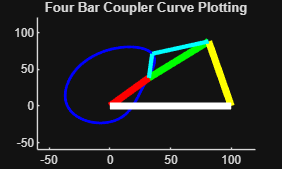


format short g

a=50; b=70; c=90; d=100; e=33; alpha=40;
ar = alpha*pi/180;
theta = 50:1:410;
T = theta*pi/180;

f = sqrt(a^2 + d^2 - 2*a*d*cos(T));

figure;
for i = 1:length(theta)
    G(i) = atan((a*sin(T(i))) / (d - a*cos(T(i))));
    Bita(i) = acos((f(i)^2 + b^2 - c^2) / (2*b*f(i))) - G(i);

    X(i) = a*cos(T(i)) + e*cos(ar + Bita(i));
    Y(i) = a*sin(T(i)) + e*sin(ar + Bita(i));

    hold on;
    title('Four Bar Coupler Curve Plotting')
    xlim([-60 120]); ylim([-60 120]);
    plot(X, Y, 'b', 'LineWidth', 2)

    Trace = viscircles([X(i) Y(i)], 2, 'Color', 'w');

    Cx = [0 a*cos(T(i)) b*cos(Bita(i))+a*cos(T(i)) d a*cos(T(i))+e*cos(Bita(i)+ar)];
    Cy = [0 a*sin(T(i)) b*sin(Bita(i))+a*sin(T(i)) 0 a*sin(T(i))+e*sin(Bita(i)+ar)];

    crank=line([0 Cx(2)],[0 Cy(2)],'color','r','linewidth',5);
    coupler=line([Cx(2) Cx(3)],[Cy(2) Cy(3)],'color','g','linewidth',5);
    output=line([Cx(3) d],[Cy(3) 0],'color','y','linewidth',5);
    fix=line([0 d],[0 0],'color','w','linewidth',5);
    eline=line([Cx(2) Cx(5)],[Cy(2) Cy(5)],'color','c','linewidth',3);
    eoline=line([Cx(5) Cx(3)],[Cy(5) Cy(3)],'color','c','linewidth',3);

    pause(0.005)
    delete(crank); delete(coupler); delete(output);
    delete(eline); delete(eoline); delete(Trace);
end

crank=line([0 Cx(2)],[0 Cy(2)],'color','r','linewidth',5);
coupler=line([Cx(2) Cx(3)],[Cy(2) Cy(3)],'color','g','linewidth',5);
output=line([Cx(3) d],[Cy(3) 0],'color','y','linewidth',5);
fix=line([0 d],[0 0],'color','w','linewidth',5);
eline=line([Cx(2) Cx(5)],[Cy(2) Cy(5)],'color','c','linewidth',3);
eoline=line([Cx(5) Cx(3)],[Cy(5) Cy(3)],'color','c','linewidth',3);